# Rad229 - Lecture 9:  Gradient-Echo Sequences

## lec9_01.m:  bSSFP Signal Magnitude and Phase

This example simply calculates the bSSFP signal vs frequency, for parameters that can be varied.

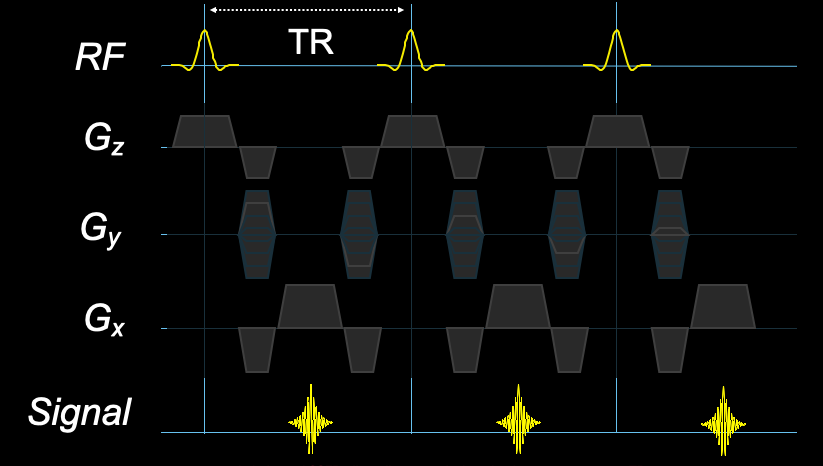

% Lecture 9, Example 01
%
% Balanced SSFP signal plot

TR = 5;         % ms
TE = 0; % ms
flip = 5;      % degrees
T1 = 1000;      % ms
T2 = 200;       % ms
rfdphase=180;    % degrees per TR
flips = [60,90,30,10,5,1];    % degrees
fliplist = [1];             % Just do one flip angle to start
%fliplist = 1:length(flips);    % All flip angles in list
labels = {'60','90','30','10','5','1'};

tt=sprintf('TR/TE = %d/%d ms, Flip=%d deg, T1/T2=%d/%d ms',TR,TE,flip,T1,T2);
disp(tt);

TR/TE = 5/0 ms, Flip=5 deg, T1/T2=1000/200 ms


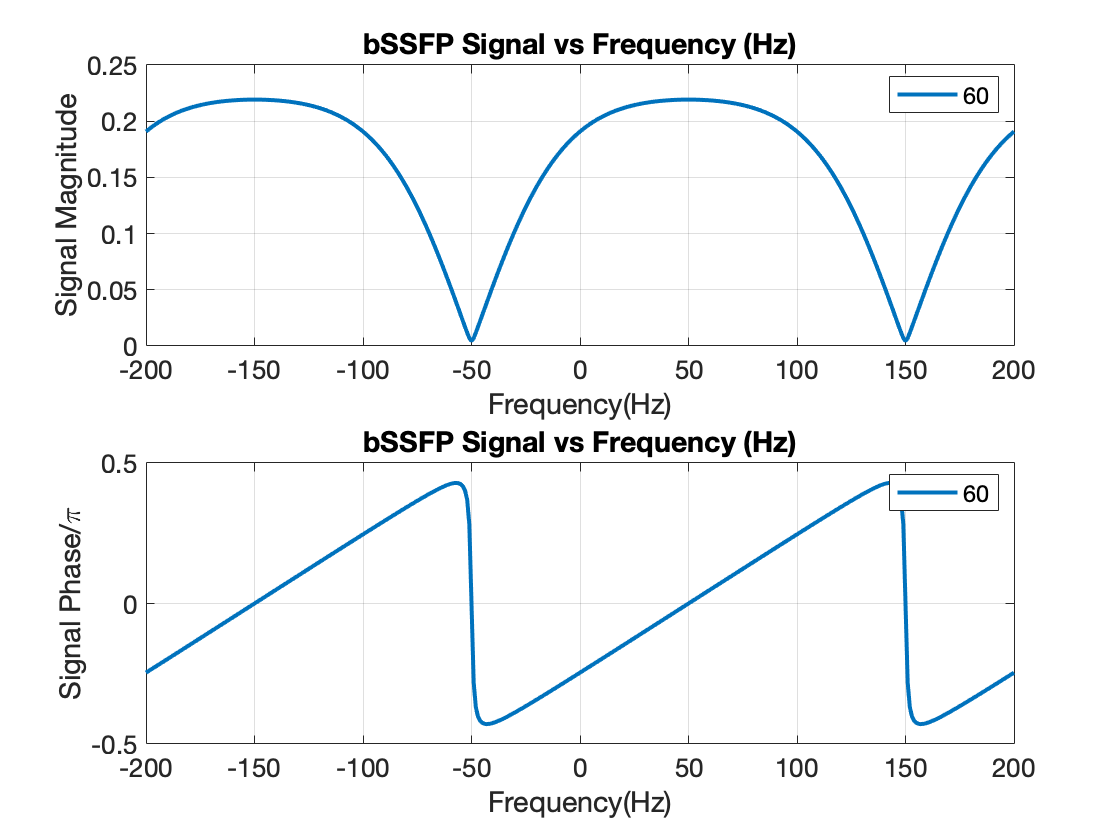


df = -200:200;
s = zeros(length(df),length(flips(fliplist)));

for f=1:length(flips(fliplist))
  for k=1:length(df);
    s(k,f) = bssfp(flips(fliplist(f)),TR,TE,T1,T2,df(k)+1000/TR*(rfdphase/360));
  end;
end;

set(0,'defaultAxesFontSize',14);        % Default font sizes
set(0, 'DefaultLineLineWidth', 2);      % Default line width
figure(1);
subplot(2,1,1);
plot(df,abs(s)); 
lplot('Frequency(Hz)','Signal Magnitude','bSSFP Signal vs Frequency (Hz)');
legend(labels{fliplist});

subplot(2,1,2);
plot(df,angle(s)/pi); 
lplot('Frequency(Hz)','Signal Phase/\pi','bSSFP Signal vs Frequency (Hz)');
legend(labels{fliplist});

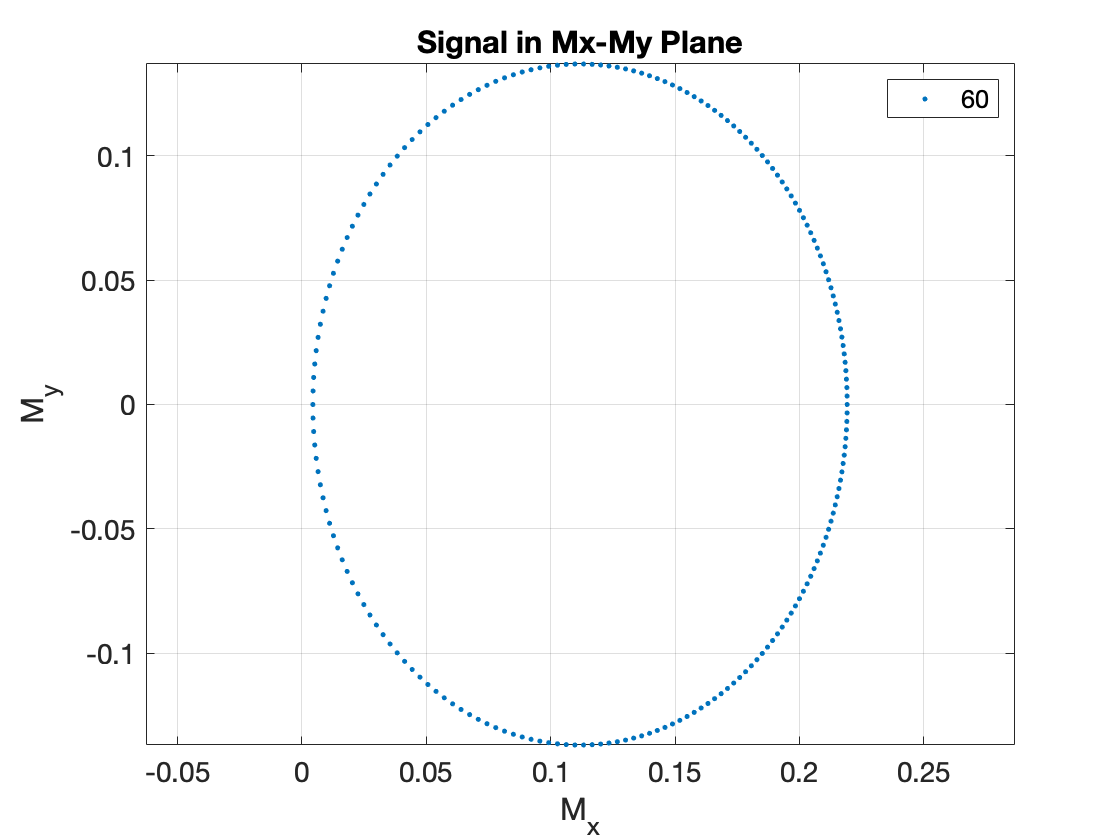


figure(2);
plot(real(s),imag(s),'.');
lplot('M_x','M_y','Signal in Mx-My Plane');
axis equal;
legend(labels{fliplist});

Note that the ellipsoid model does start to break down at low flip angles.  Note the 5° locus of points in the signal collapses to a line.

Exercises:

1) Change the Δθ for the RF:  180° to 0° to other values

2) Change the flip angle to 90°, 30° then 10° then 5° then 1°

3) Change the TE to TR/2, then TR

## lec9_02.m:  Gradient-Spoiled Signal

Similar to the previous example, but now we are plotting the gradient-spoiled signal as well.

% Lecture 9, Example 02
%
% GRE signal, vs bSSFP.

TR = 5;         % ms
TE = 0;         % ms
flip = 30;      % degrees
T1 = 1000;      % ms
T2 = 200;       % ms
rfdphase=180;    % degrees per TR
flips = [60,90,30,10,5,1];    % degrees
fliplist = [1];             % Just do one flip angle to start
labels = {'60','90','30','10','5','1'};

tt=sprintf('TR/TE = %d/%d ms, Flip=%d deg, T1/T2=%d/%d ms',TR,TE,flip,T1,T2);
disp(tt);

TR/TE = 5/0 ms, Flip=30 deg, T1/T2=1000/200 ms


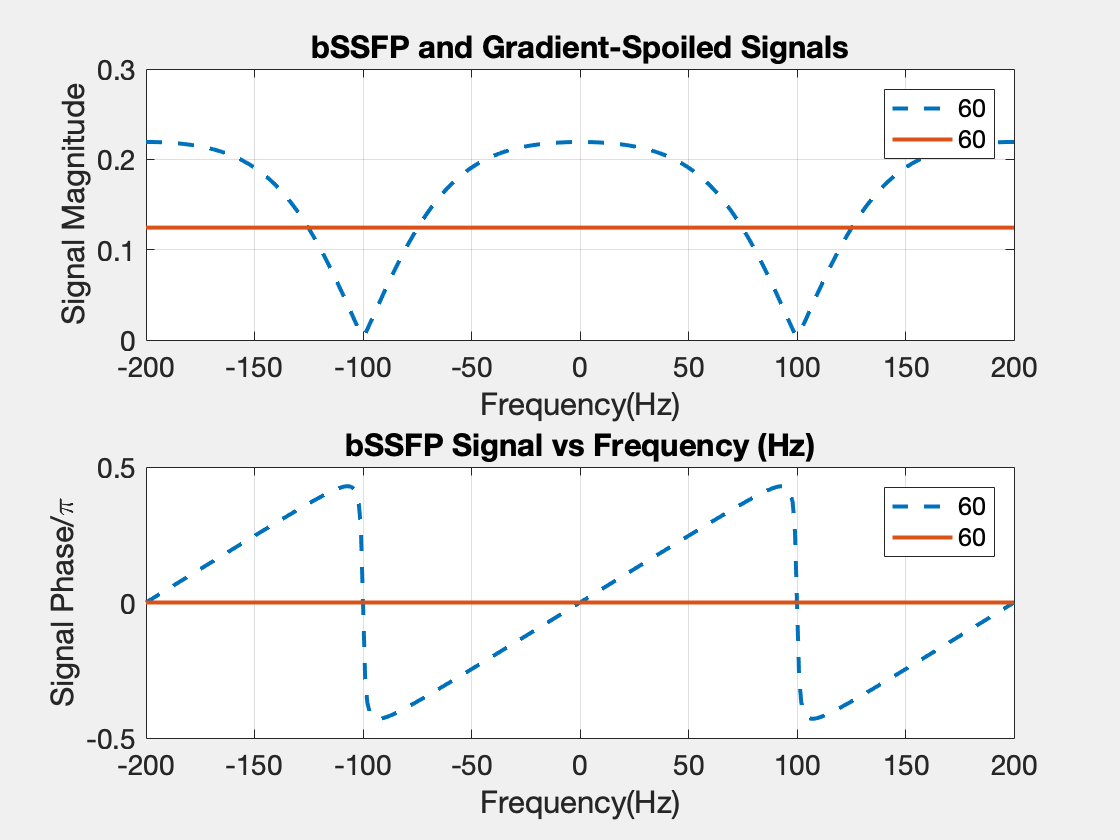


df = -200:200;
s = zeros(length(df),length(flips(fliplist)));
gre=s;

for f=1:length(flips(fliplist))
  for k=1:length(df);
    s(k,f) = bssfp(flips(fliplist(f)),TR,TE,T1,T2,df(k)+1000/TR*(rfdphase/360));
    gre(k,f) = gresignal(T1,T2,TE,TR,flips(fliplist(f)));
  end;
end;

set(0,'defaultAxesFontSize',14);        % Default font sizes
set(0, 'DefaultLineLineWidth', 2);      % Default line width
figure(1);
subplot(2,1,1);
plot(df,abs(s),'--');  hold on;
plot(df,abs(gre),'-');  hold off;
lplot('Frequency(Hz)','Signal Magnitude','bSSFP and Gradient-Spoiled Signals');
legend({labels{fliplist},labels{fliplist}});

subplot(2,1,2);
plot(df,angle(s)/pi,'--'); hold on;
plot(df,angle(gre)/pi,'-'); hold off;
lplot('Frequency(Hz)','Signal Phase/\pi','bSSFP Signal vs Frequency (Hz)');
legend({labels{fliplist},labels{fliplist}});

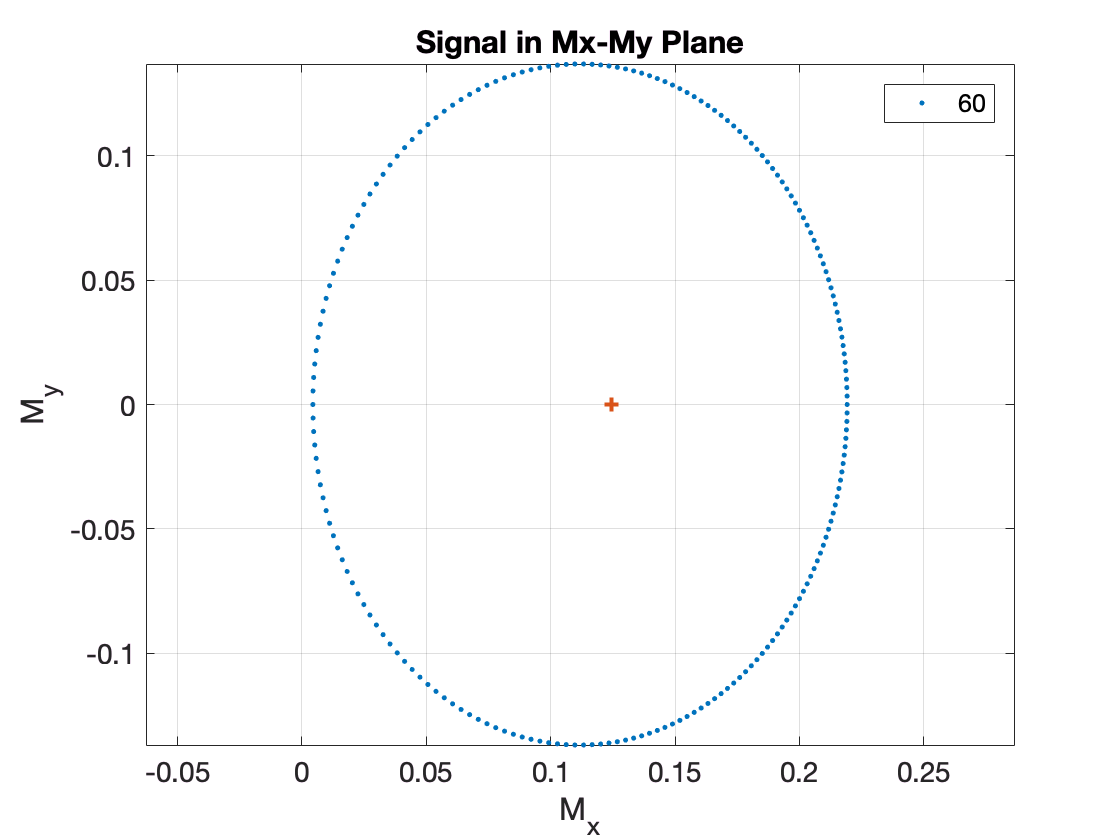


figure(2);
plot(real(s),imag(s),'.'); hold on;
plot(real(gre),imag(gre),'+'); hold off;
lplot('M_x','M_y','Signal in Mx-My Plane');
axis equal;
legend(labels{fliplist});

## lec9_03.m:  Signals vs Flip Angle

Here we plot signals vs flip angle for bSSFP (both 0 and 180° phase cycling), gradient-spoiled and RF-spoiled sequence.

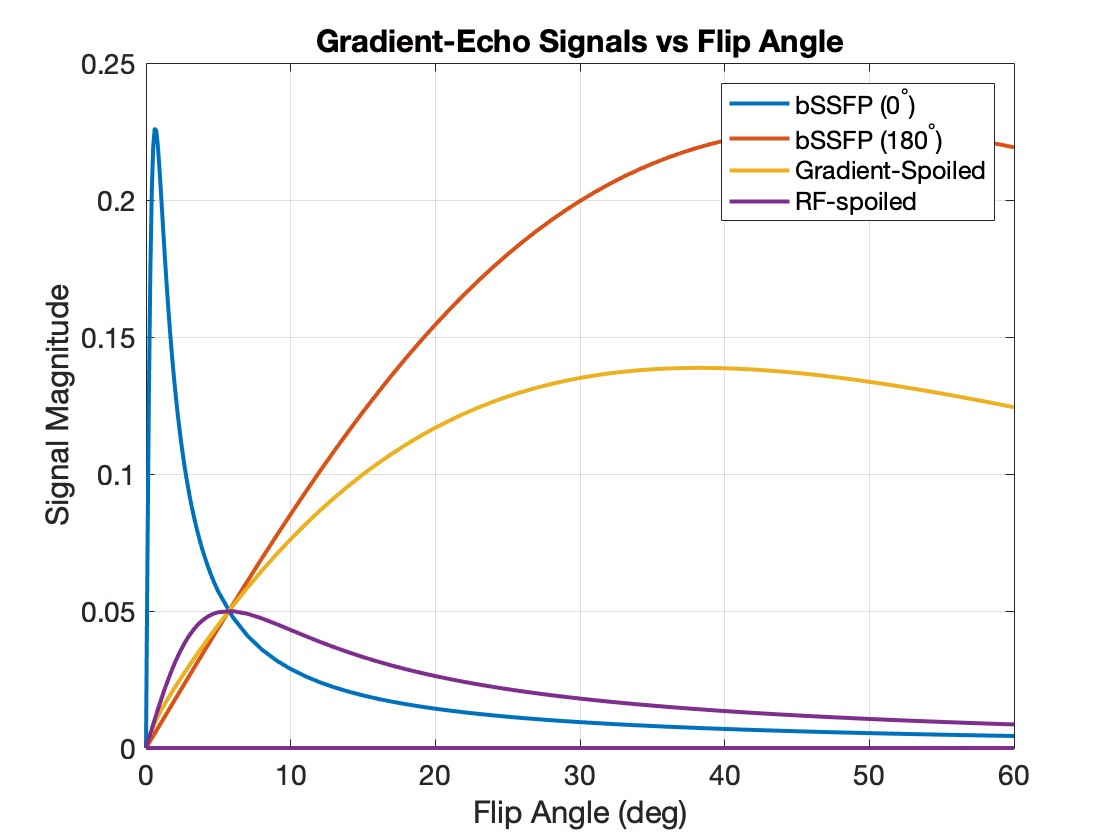

% Lecture 9, Example 03
%
% Signals vs flip angled for bSSFP, gradient-spoiled, RF-spoiled.

TR = 5;         % ms
TE = 0;         % ms
flips = [[0:0.1:5] [6:60]];      % degrees
T1 = 1000;      % ms
T2 = 200;       % ms

sbssfp0 = zeros(length(flips));
sbssfp180 = sbssfp0;
sgre= sbssfp0;
srfsp= sbssfp0;

for f=1:length(flips)
  sbssfp0(f) = bssfp(flips(f),TR,TE,T1,T2,0);
  sbssfp180(f) = bssfp(flips(f),TR,TE,T1,T2,500/TR);
  sgre(f) = gresignal(T1,T2,TE,TR,flips(f));
  srfsp(f) = exrecsignal(T1,T2,TE,TR,flips(f));
end;

set(0,'defaultAxesFontSize',14);        % Default font sizes
set(0, 'DefaultLineLineWidth', 2);      % Default line width
figure(3);
plot(flips,abs(sbssfp0),flips,abs(sbssfp180),flips,abs(sgre),flips,abs(srfsp));
lplot('Flip Angle (deg)','Signal Magnitude','Gradient-Echo Signals vs Flip Angle');
legend('bSSFP (0^\circ)','bSSFP (180^\circ)','Gradient-Spoiled','RF-spoiled');

Exercises:

1) Change T1 - how does the Ernst angle change?

2) Change T2 - what changes?

# Repeated Test with epg_gradecho.m

epg_gradecho.m uses EPG to solve for the steady-state signal in the 3 main gradient-echo sequences.  We can repeat the signal-vs-flip-angle plot above using this function here:

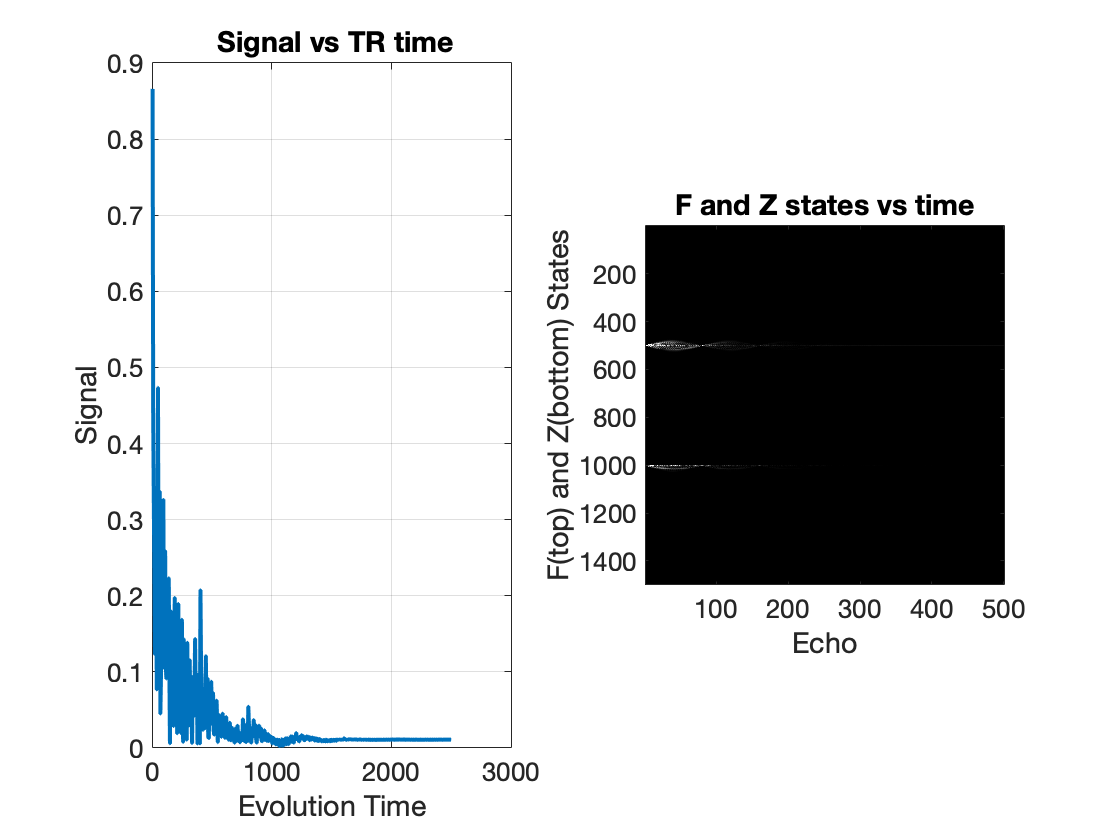

% Lecture 9, Example 04
%
% EPG simulation of Signals vs flip angled for bSSFP, gradient-spoiled, RF-spoiled.
% Notice that this calls ONE function that simulates any sequence iteratively
% to the steady state.  It should clarify the sequence steps for each 
% gradient-echo variant.
%
TR = 5;         % ms
TE = 0;         % ms
flips = [[0:0.1:5] [6:60]]*pi/180;      % radians
T1 = 1000;      % ms
T2 = 200;       % ms

sbssfp0 = zeros(length(flips));
sbssfp180 = sbssfp0;
sgre= sbssfp0;
srfsp= sbssfp0;

for f=1:length(flips)
  sig = epg_gradecho(flips(f),T1,T2,TR,TE,0);
  sbssfp0(f) = sig(end);
  sig = epg_gradecho(flips(f),T1,T2,TR,TE);
  sbssfp180(f) = sig(end);
  sig = epg_gradecho(flips(f),T1,T2,TR,TE,0,0,1);
  sgre(f) = sig(end); 
  sig = epg_gradecho(flips(f),T1,T2,TR,TE,0,117/180*pi,1);
  srfsp(f) = sig(end);
end;

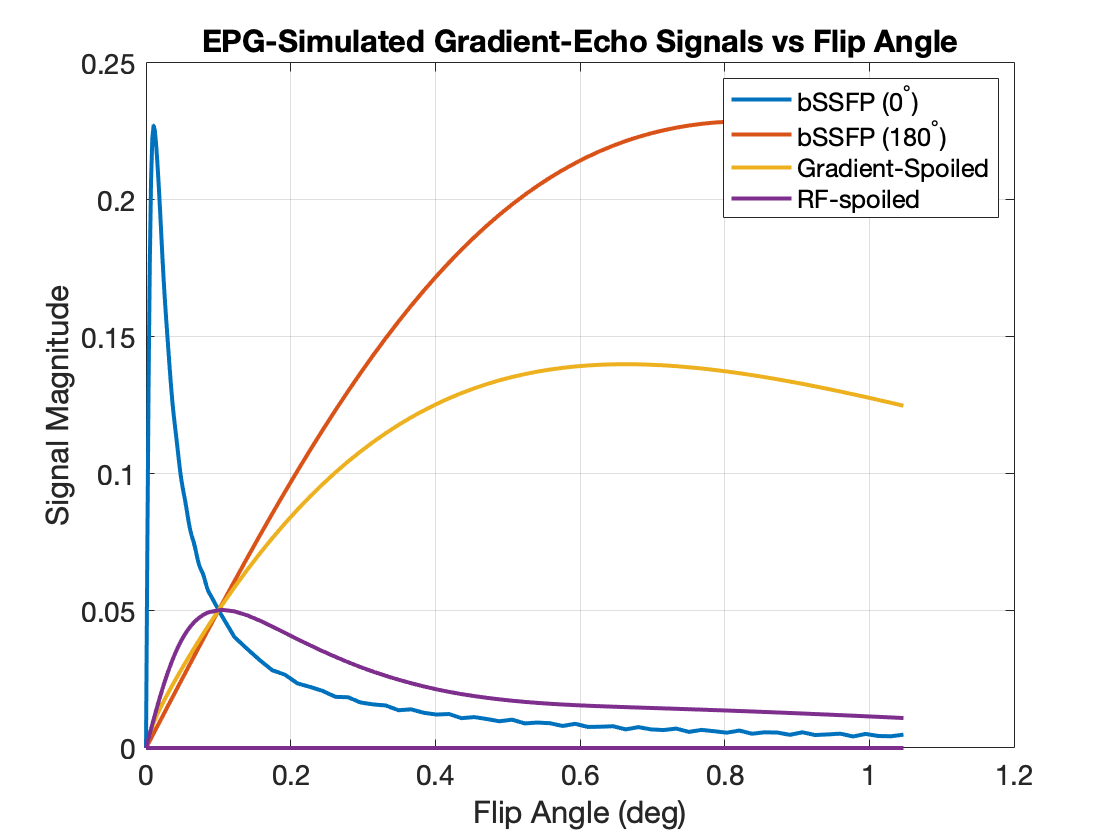


set(0,'defaultAxesFontSize',14);        % Default font sizes
set(0, 'DefaultLineLineWidth', 2);      % Default line width
figure;
plot(flips,abs(sbssfp0),flips,abs(sbssfp180),flips,abs(sgre),flips,abs(srfsp));
lplot('Flip Angle (deg)','Signal Magnitude','EPG-Simulated Gradient-Echo Signals vs Flip Angle');
legend('bSSFP (0^\circ)','bSSFP (180^\circ)','Gradient-Spoiled','RF-spoiled');